## Plot ISC Earthquake Data

setupISCtoolbox; % Adds the paths to Functions etc

## Summarize earthquake Data Set

This Live Script gives us a first overview of a ISC data set, stored in the ISC_matlab_toolbox.

For a given data set, we plot the PRIME locations, and look at the number and magnitude of earthquakes over time.

## Pre-step or preparation work

This example is set up to use a pre-made stored data set of Global earthquake in 2020. You can run this example on any data set. To learn how to create your own ISC earthquake data set, please see the 'ISC_data_download' Live Script

## Part 1: Load Data

Here you can either set the path to one of the pre-downloaded data sets (In the directory *Data/Example_ISC_Data* or* Data/Downloaded_ISC_Data*), or you can set the path to your own data set, downloaded using Workbook 1.

% load('Data/Downloaded_ISC_Data/Japan_2018_2021_mb4_0plus.mat');
% load('Data/Downloaded_ISC_Data/Morroco_1964_2023_mb4_0plus.mat');
% load('Data/Downloaded_ISC_Data/Afganistan_1964_2023_NEICmb3_0plus.mat');
% load('Data/Downloaded_ISC_Data/Afganistan_2014_2023_ISCmb5_0plus.mat');
load('Data/Downloaded_ISC_Data/Afganistan_phases_2023_2024_ISCmb1_0plus.mat');
% load('Data/Downloaded_ISC_Data/Turkey_Feb2023_NEIC_mb4_5plus.mat');
% load('Data/Downloaded_ISC_Data/Morrocco_phases_2023_2024_ISCmb1_0plus.mat');
% load('Data/Downloaded_ISC_Data/Morrocco_Sep2023_any_mb0_0plus.mat');
% load('Data/Downloaded_ISC_Data/Morrocco_Aug2023_Jan2024_mb0_0plus.mat');
% load ('Data/Downloaded_ISC_Data/Global_2019_2020_gCMT_Mw5_4lus.mat');


% load ('Data/Downloaded_ISC_Data/Global_2019_2020_gCMT_Mw5_4lus.mat');
% load ('Data/Downloaded_ISC_Data/Turkey_Feb2023_NEIC_mb4_5plus.mat');

%load('Data/Downloaded_ISC_Data/Tonga_Phases_Jan2023_mb0_0plus.mat');
%load('Data/Downloaded_ISC_Data/Tonga_Mar2021_mb5_0plus.mat');
%load('Data/Downloaded_ISC_Data/Tonga_Feb_May2021_mb5_0plus.mat');

## Part 2: Extract and Plot Earthquake Locations from the data set

Here we get the earthquake location data from the data table called 'Primes'. These are the earthquake locations that the ISC review process considers to be the most reliable, of the many reported to the ISC. for information, anything between 1 and 20 different Earthquake locations can be reported to the ISC for a single earthquake. The ISC combines the information from all of these to provide a 'final' location which will often be the 'prime' hypocentre. In other cases, particularly for low (< 3.5mb) magnitude earthquakes, the 'prime' is simply set to a the location provided by a reliable local earthquake reporter (e.g. The Japanese Meteorological Agency, [JMA](https://www.jma.go.jp/jma/indexe.html), in Japan)

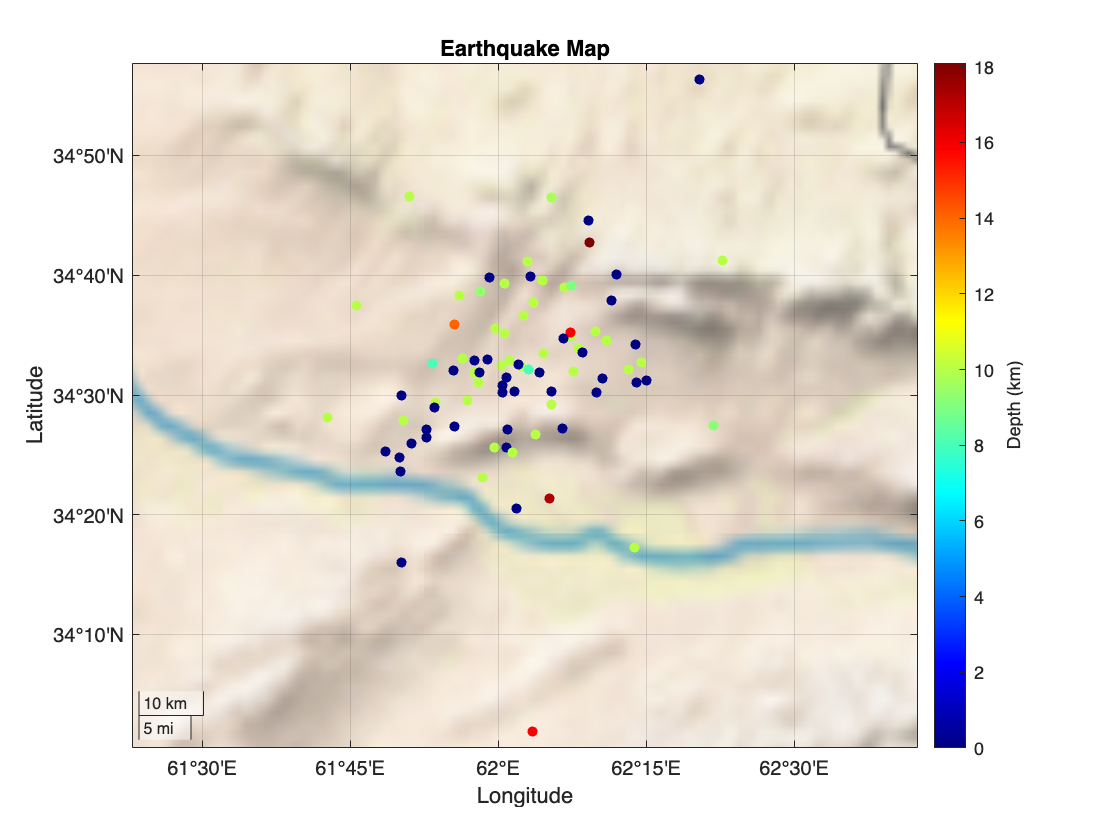

eq_lats = allPrimes.Latitude;
eq_lons = allPrimes.Longitude;
eq_depths = allPrimes.Depth;
eq_times = allPrimes.Date;

geobasemap landcover;
hold on;
geoscatter(eq_lats, eq_lons, 25, eq_depths, 'filled');
colormap jet;

c = colorbar;
c.Label.String = 'Depth (km)';
title('Earthquake Map');

## Part 3: Extract and Plot Earthquake Magnitudes

Here we explore the 'Magnitudes' table of the ISC Earthquake toolbox data structure.

If you explore the ISC data, either via the website (isc.ac.uk) or via the ISC_MATLAB_toolbox (your here!) you will see that most earthquakes are not reported with a single Earthquake magnitude, but with many. This is partly because, as with the locations, several agencies report this information. However there are also several different types of earthquake magnitude, as we will explore in more detail in a later Live Script (*ISCtoolbox_WB3_Exploring_Earthquake_Magnitudes*) these values can be very different. Get local copy of the event IDs for the data set

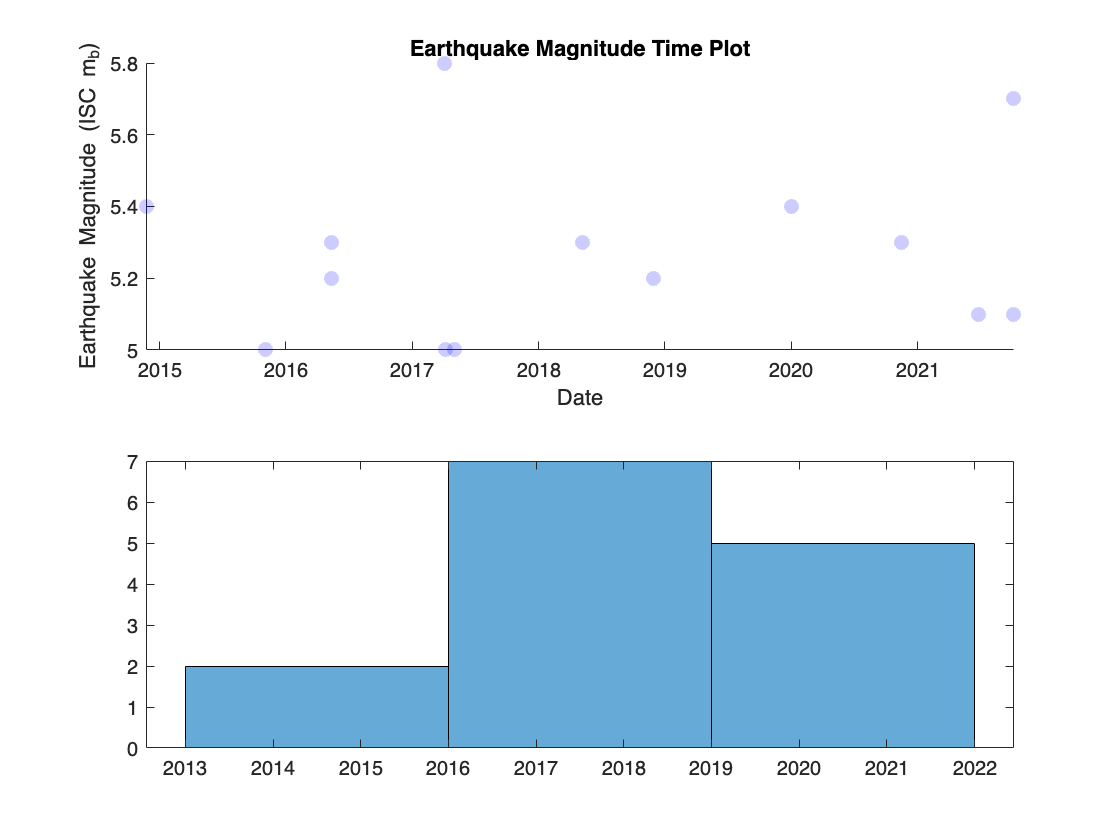

% Get local copy of the event IDs for the data set
prime_evids = allPrimes.EventID;

for n = 1:size(prime_evids, 1)

    % Get evid for given event
    evid = prime_evids(n);
    evid_idx = allMagnitudes.EventID == evid;
    
    % Get magnitudes for that event
    event_mags = allMagnitudes(evid_idx,:);

    % Get ISC mb for that event, set to NaN if not available
    idx = event_mags.MagnitudeType == 'mb';
    event_mags = event_mags(idx,:); 
    idx = event_mags.Author == 'IDC';
    event_mags = event_mags(idx,:);

    if size(event_mags,1) == 1
        isc_mbs(n) = event_mags.Magnitude;
    else
        isc_mbs(n) = NaN;
    end
end

figure; subplot(2,1,1)
scatter(eq_times, isc_mbs, 500, '.', 'MarkerFaceColor','b', ...
    'MarkerEdgeColor','b','MarkerFaceAlpha',0.2,'MarkerEdgeAlpha',.2);


title('Earthquake Magnitude Time Plot');
xlabel('Date');
ylabel('Earthquake Magnitude (ISC m_b)');

subplot(2,1,2);
histogram(eq_times);

## Part 4: Plot the spatial and depth distribution of the Earthquakes

Here we plot a map of earthquakes in the selected data base (top left) and the earthquake latitude (top right), and earthquake depths vs then earthquake longitude (bottom left).

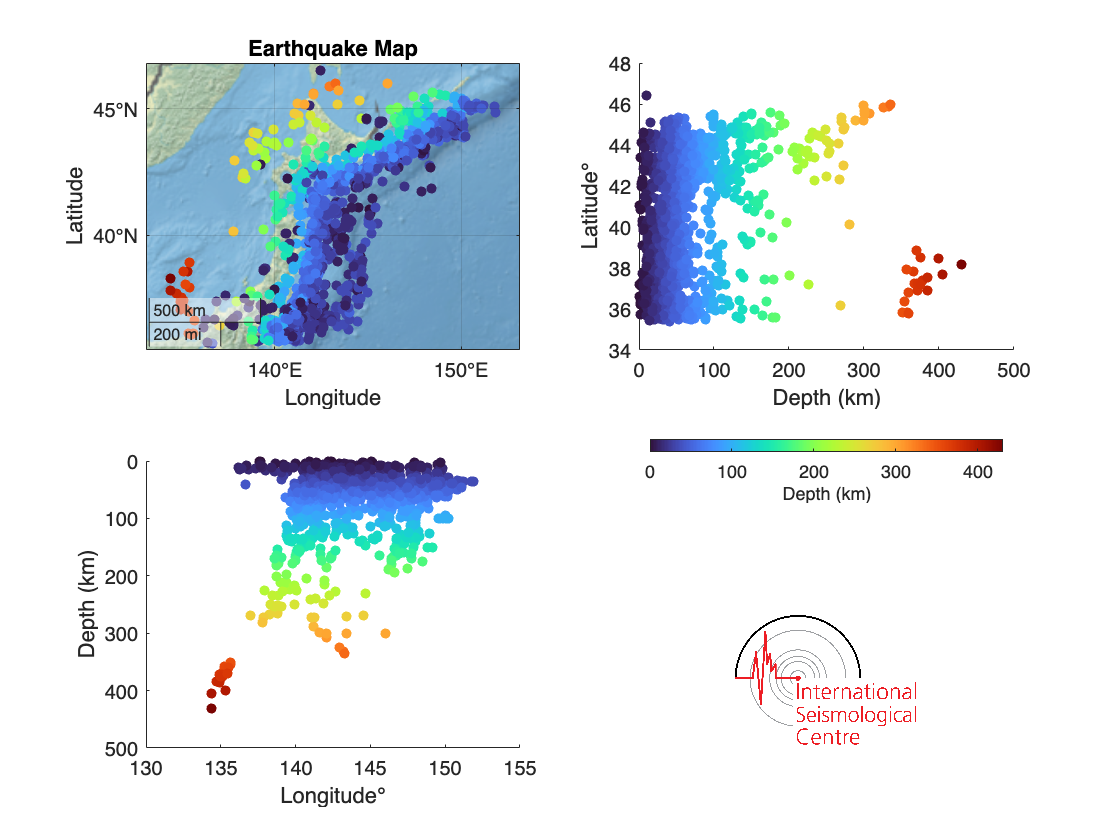

% Plot the Earthquake map
figure; subplot(2,2,1)
geoscatter(eq_lats, eq_lons, 25, eq_depths, 'filled');
geobasemap landcover;
title('Earthquake Map');

% Plot the Earthquake depths vs Latitude
subplot(2,2,2);
scatter(eq_depths, eq_lats, 25, eq_depths, 'filled');
xlabel('Depth (km)');
ylabel(['Latitude' char(176)]);
clim([0, max(eq_depths)]);

% Plot the Earthquake depths vs Longitudes
subplot(2,2,3);
scatter(eq_lons, eq_depths, 25, eq_depths, 'filled');
xlabel(['Longitude' char(176)]);
ylabel('Depth (km)');
clim([0, max(eq_depths)]);
axis ij;

% Plot the depth colorbar
subplot(4,2,6);
% ylim([-40, 0]); 
axis off
colormap turbo;
c = colorbar('north');
c.Label.String = 'Depth (km)';
% clim([0,700])
clim([0, max(eq_depths)])

% Plot the logo
subplot(4,2,8);
set(gcf,'color','w');
[X,cmap] = imread('Data/Example_ISC_Data/isc.png');
imshow(X,cmap);

saveas(gcf, 'Japan_map_profiles.png');

## Part 5: Plot earthquake distribution in 3D

Here we create a 3D scatter plot, showing earthquake depth distributions.

figure
scatter3(eq_lats*-1, eq_lons, eq_depths*-1, 100, eq_depths, '.')
colormap turbo; 

c = colorbar;
c.Label.String = 'Earthquake Depth (km)';

xlabel('Latitude');
ylabel('Longitude');
zlabel('(Negative) Depth (km)');





## Part 6: Plot the depth distribution of the Earthquakes over time

Plots the depth of earthquakes over time. Top left, the full depth range. Bottom left, zoomed into the shallowest 50 km of earthquakes. Top right, histogram of earthquake depths over the full range. Bottom right, histogram of earthquake depths for the shallowest 50 km of earthquakes.

% Plot the earthquake depths over time (full depth range)
figure;
subplot(3,3,1:2)
scatter(eq_times, eq_depths, 500, '.', 'MarkerFaceColor','b', ...
    'MarkerEdgeColor','b','MarkerFaceAlpha',0.2,'MarkerEdgeAlpha',.2);
title('Earthquake Depth Time Plot');
xlabel('Date');
ylabel('Earthquake Depth (km)');

% Plot the earthquake depths over time (top 50 km)
subplot(3,3,4:5);
scatter(eq_times, eq_depths, 500, '.', 'MarkerFaceColor','b', ...
    'MarkerEdgeColor','b','MarkerFaceAlpha',0.2,'MarkerEdgeAlpha',.2);
ylim([0 50]);
title('Earthquake Depth Time Plot');
xlabel('Date');
ylabel('Earthquake Depth (km)');

% Plot horizontal depth histogram
subplot(3,3,3); hold on;
max_depth_bin = round((max(eq_depths)/10)+1);
xbins = linspace(0, max_depth_bin*10, max_depth_bin+1);
[counts, bins] = hist(eq_depths, xbins);
barh(bins,counts);

% Remove depths that are exactly 10 or exactly 35 km, as most likely fixed.
% This could be improved
eq_freedepths = eq_depths;
eq_freedepths(eq_freedepths==10) = NaN;
eq_freedepths(eq_freedepths==35) = NaN;

xlabel('Number of Events');
ylabel('Earthquake Depth (km)');
title('Depth Histogram');

% Plot horizontal depth histogram
subplot(3,3,6); hold on;
max_depth_bin = round((max(eq_depths)/1)+1);

xbins = linspace(0, max_depth_bin*1, max_depth_bin+1);
[counts, bins] = hist(eq_depths, xbins);
barh(bins,counts);

[counts2, bins2] = hist(eq_freedepths, xbins);
barh(bins2,counts2);
ylim([0 50]);

xlabel('Number of Events');
ylabel('Earthquake Depth (km)');
title('Depth Histogram');

subplot(3,3,9); hold on;
barh(bins,counts); barh(bins,counts);
xlim([-500,-499]);
legend('Depth Distribution (including fixed depths)', ...
    'Depth Distribution (excluding fixed depths)');
axis off;